# Example of taking images from Andor CCDs

#### Initialize Andor CCDs

Handle = initializeAndor();


******Start initialization******

Camera (serial: 19330, handle: 201) is set to current CCD
Camera (serial: 19331, handle: 100) is set to current CCD


#### Select the CCD to use

setCurrentAndor(19331, Handle)

Camera (serial: 19331, handle: 100) is set to current CCD


#### Set the operation mode

setModeFK(exposure=0.2, num_frames=8, external_trigger=false)


******Fast Kinetic mode******

Current camera serial number: 19331
Number of frames: 8
Exposure time: 0.200s
Kinetic cycle time: 0.201s
Trigger: Internal



#### Take a single image

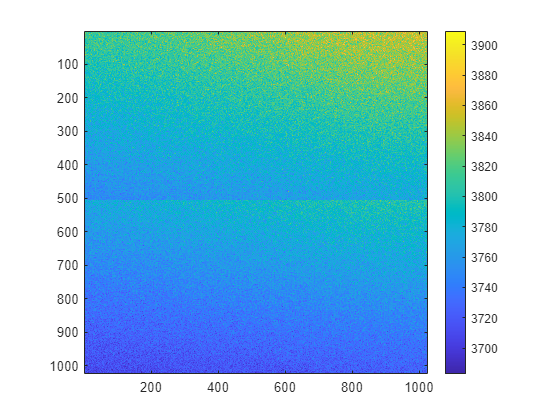

sample = acquireAndorImage();

figure
imagesc(sample)
daspect([1 1 1])
colorbar

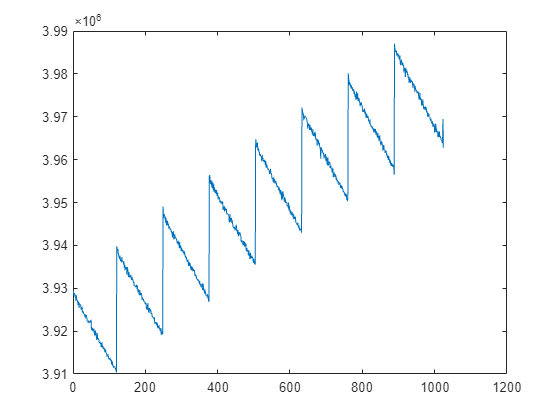

y_sum = sum(sample, 2);

figure
plot(y_sum)

#### Take a series of images with a loop

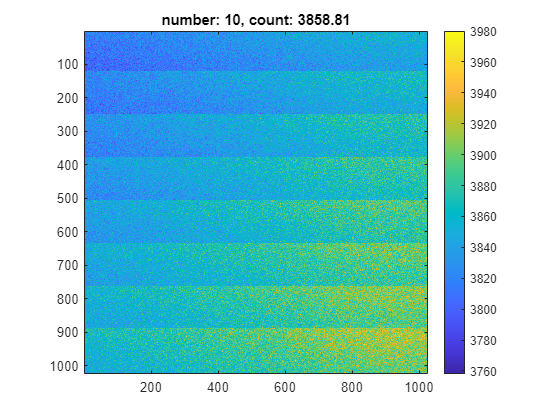

num_image = 0;
max_image = 10;

fig = figure;
while num_image < max_image

    num_image = num_image + 1;
    image = acquireAndorImage(timeout=60000);

    count = mean(image, 'all');

    figure(fig)
    imagesc(image)
    daspect([1 1 1])
    colorbar
    title(sprintf('number: %d, count: %g', num_image, count))

    drawnow
end